Pipeline to run an experiment with varying cellulase diffusivity in 2d

# Part 10: Diffusivity/InitEnzyme 2d experiments

%Temporary / diagnostic changes

%change amount of initial enzyme
%args.p10.v.initenzyme = args.p10.v.initenzyme * 1000

%remove enzyme decay
%args.p10.v.enzdecayperhour = 0;


args.p10.v.maxcycles = 1501;
%args.p10.v.maxcycles = 21;
args.p10.v.timestep = 1;
args.p10.v.lograte = 10;

%args.p10.variableInitEnzyme = true;
args.p10.v.initenzyme = args.p10.v.initialpop * args.p10.v.alpha;

args.p10.v.numExRxnSubsteps = 1;

if ~exist('remcfg','var')
    load remoteconfig;
end

%args.p10.v.writemedialog = false;
args.p10.v.writemedialog = true;

%try a larger plate:

args.p10.v.plateDiam = 8.6; %cm, measured from a physical plate (85.7mm)
args.p10.v.spaceWidth = 0.1; %cm
args.p10.v.xdim = ceil(args.p10.v.plateDiam / args.p10.v.spaceWidth);
args.p10.v.ydim = ceil(args.p10.v.plateDiam / args.p10.v.spaceWidth);

%set init cellulose
%Enzymatic assays in Den Haan et al used 20g/L cellulose
%assume 20mL of media for a standard sized (~100mm) plate
%use circular layouts
g_avicel_total = 20 * 20 / 1000;
ncells = args.p10.v.plateDiam / args.p10.v.spaceWidth;
g_avicel_per_mol = (180.156 - 17) * args.p10.v.glcpercellulose;
mol_avicel_total = g_avicel_total / g_avicel_per_mol;
mol_avicel_per_cell = mol_avicel_total / ncells;
args.p10.v.initcellulose = mol_avicel_per_cell;

%reduce initial cellulose to reflect incomplete conversion
args.p10.v.initcellulose = args.p10.v.initcellulose * 0.27;
v_default.initcellulose = args.p10.v.initcellulose;


%include draining at edges:
args.p10.v.drainatedges = true;
%args.p10.v.drainatedges = false;

args.p10.diffscales = 10.^([-4 -3.5 -3 -2.5 -2 -1.5 -1 0 1 2]);
args.p10.diffscales = 10.^([-4 -3.5 -3 -2.5 -2 -1.75 -1.5 -1 0]);
args.p10.diffscales = 10.^([-4 -3.5 -3 -2.5 -2 -1.75 -1.5 -1.25 -1 -.5 0]);
args.p10.diffscales = 10.^([-4 -3.5 -3 -2.5 -2 -1.75 -1.5 -1.25 -1 -.5 0 .5 1 1.5 2]);
args.p10.diffscales = 10.^([-4 -3.5 -3 -2.5 -2 -2.5 -1 -.5 0 .5 1 1.5 2 2.5 3 3.5 4]);
args.p10.enzscales = 10.^([-3 -2.75 -2.5 -2.25 -2 -1 0]);
args.p10.enzscales = 10.^([-2.7 -2.65 -2.6 -2.55 -2.5 -2.25 -2]);
%args.p10.enzscales = 10.^([-2.7 -2.65 -2.6]);
args.p10.enzscales = 10.^([-3 -2.75 -2.7 -2.65 -2.6 -2.55 -2.5 -2.25 -2 -1.5 -1 -.5 0]);
args.p10.enzscales = 10.^([-1 0 1 2 3 4 5]);
args.p10.enzscales = 10.^([2.5 3 3.5 4]);
%args.p10.enzscales = 1;
args.p10.enzamts = args.p10.enzscales * args.p10.v.initenzyme;

%Generate the COMETS files
if runPart10    
    args.p10.v_default = v_default;
    layouts10 = part10_generation_remote(args.p10);
    %[layouts10,remcfg] = runCometsRemotely(layouts10,remcfg);

else
    if ~exist('dat10','var')
        load([datadir '\dat10.mat']);
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

%Run the push/execute/pull scripts here
% % system('bash C:/sync/biomes/cellulose/optima/temp/pushcomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/runremotecomets.sh')
% % system('bash C:/sync/biomes/cellulose/optima/temp/pullcomets.sh')


%Load the results and apply to dat10

remcfg.batchnum = '191030153440' %temp bookmark

remcfg = struct with fields:
     hostname: 'scc1'
     username: 'mquintin'
      keyfile: 'C:\sync\biomes\scripts\remote\keys\id_rsa_noprompt'
    cometsjar: '~/comets_branch.jar'
       ncores: 8
     batchnum: '191030153440'


disableMediaLog = true;
disableMediaLog = false;
for i = 1:length(layouts10)
    layouts10{i}.params.writeMediaLog = ~disableMediaLog;
end

if runPart10
   dat10 = part10_parseRemoteResults(layouts10,remcfg.batchnum);
   %dat10.layouts = cell(size(layouts10,1),1);
end

Loading Biomass ./log_1/biomass.m
Loading Media ./log_1/media.m
Loading Biomass ./log_2/biomass.m
Loading Media ./log_2/media.m
Loading Biomass ./log_3/biomass.m
Loading Media ./log_3/media.m
Loading Biomass ./log_4/biomass.m
Loading Media ./log_4/media.m
Loading Biomass ./log_5/biomass.m
Loading Media ./log_5/media.m
Loading Biomass ./log_6/biomass.m
Loading Media ./log_6/media.m
Loading Biomass ./log_7/biomass.m
Loading Media ./log_7/media.m
Loading Biomass ./log_8/biomass.m
Loading Media ./log_8/media.m
Loading Biomass ./log_9/biomass.m
Loading Media ./log_9/media.m
Loading Biomass ./log_10/biomass.m
Loading Media ./log_10/media.m
Loading Biomass ./log_11/biomass.m
Loading Media ./log_11/media.m
Loading Biomass ./log_12/biomass.m
Loading Media ./log_12/media.m
Loading Biomass ./log_13/biomass.m
Loading Media ./log_13/media.m
Loading Biomass ./log_14/biomass.m
Loading Media ./log_14/media.m
Loading Biomass ./log_15/biomass.m
Loading Media ./log_15/media.m
Loading Biomass ./log_16/bio

dat10.biomass_max = cellfun(@(x) x(end),dat10.biomass_total);

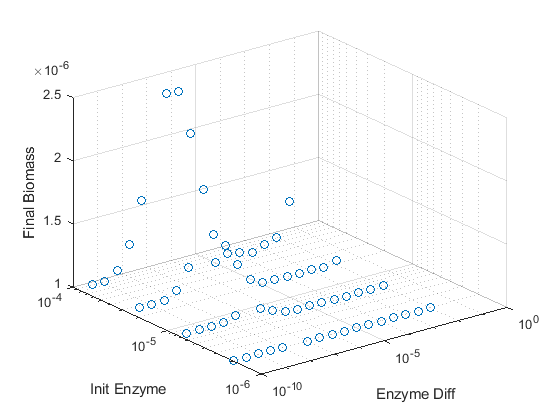

scatter3(dat10.diff_enz,dat10.enz_init,dat10.biomass_max);
set(gca,'yscale','log');
set(gca,'xscale','log');
xlabel('Enzyme Diff');
ylabel('Init Enzyme');
zlabel('Final Biomass');

x = unique(dat10.diff_enz);
y = unique(dat10.enz_init);
%map, and interpolate missing data
z = griddata(dat10.diff_enz,dat10.enz_init,dat10.biomass_max,unique(dat10.diff_enz),unique(dat10.enz_init)','linear');

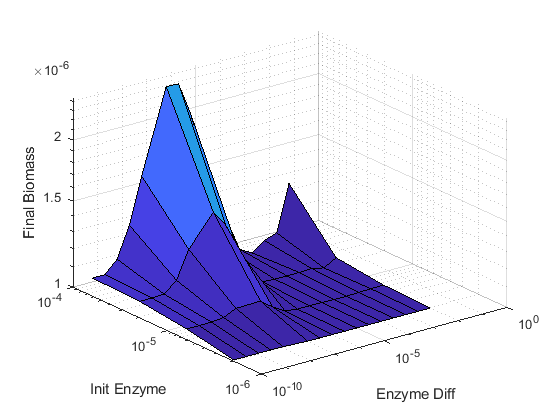

%[xo yo zo] = prepareSurfaceData(x,y,z);
%zo = reshape(zo,[length(y) length(x)]);
surf(x,y,z);
set(gca,'yscale','log');
set(gca,'xscale','log');
set(gca,'zscale','log');
xlabel('Enzyme Diff');
ylabel('Init Enzyme');
zlabel('Final Biomass');

%just the nonzero growth data
x = unique(dat10.diff_enz);
y = unique(dat10.enz_init);
%map, and interpolate missing data
z = griddata(dat10.diff_enz,dat10.enz_init,dat10.biomass_max,unique(dat10.diff_enz),unique(dat10.enz_init)','linear');

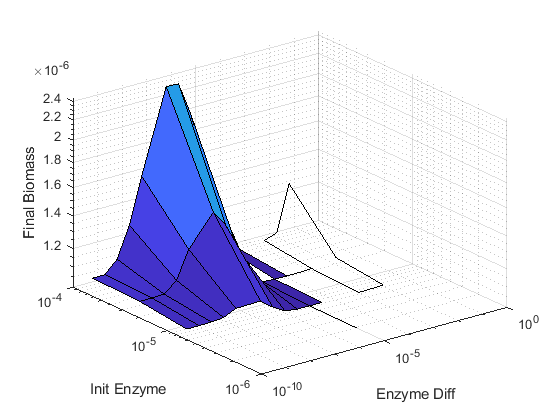

%[xo yo zo] = prepareSurfaceData(x,y,z);
%zo = reshape(zo,[length(y) length(x)]);
nzmap = z > min(z);
z2 = nan(size(z));
z2(nzmap) = z(nzmap);

surf(x,y,z2);
set(gca,'yscale','log');
set(gca,'xscale','log');
set(gca,'zscale','log');
xlabel('Enzyme Diff');
ylabel('Init Enzyme');
zlabel('Final Biomass');

%2d plots for individual init enzyme amounts
enzamt = unique(dat10.enz_init);
dat10 = sortrows(dat10,'diff_enz');
figure();
hold on;
for i = 1:length(enzamt)
    d = dat10(dat10.enz_init == enzamt(i),:);
    d = d(d.diff_enz <=10^(-5.5),:);
    plot(d.diff_enz,d.biomass_max,'linewidth',2);
end
xlabel('Enzyme diff');
ylabel('Biomass yield');
%leg = legend(num2str(log10(enzamt)),'location','eastoutside')
leg = legend({'0.02' '0.06' '0.20' '0.62'},'location','eastoutside')

leg =   Legend (0.02, 0.06, 0.20, 0.62) with properties:

         String: {'0.02'  '0.06'  '0.20'  '0.62'}
       Location: 'eastoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7878 0.4351 0.1339 0.1655]
          Units: 'normalized'

  Show all properties

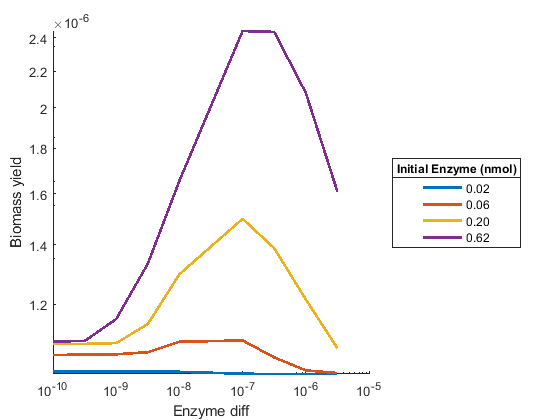

title(leg,'Initial Enzyme (nmol)');
set(gca,'yscale','log');
set(gca,'xscale','log');
hold off;

enzamt = unique(dat10.enz_init);
dat10 = sortrows(dat10,'diff_enz');
mu = cellfun(@(x) max(x),dat10.biomass_growthrate);
dat10.mu_max = mu;
figure();
hold on;
for i = 1:length(enzamt)
    d = dat10(dat10.enz_init == enzamt(i),:);
    d = d(d.diff_enz <=10^(-5.5),:);
    plot(d.diff_enz,d.mu_max,'linewidth',2);
end
xlabel('Enzyme diff');
ylabel('Maximum Growth Rate \mu (s^-^1)');
%leg = legend(num2str(log10(enzamt)),'location','eastoutside')
leg = legend({'0.02' '0.06' '0.20' '0.62'},'location','eastoutside')

leg =   Legend (0.02, 0.06, 0.20, 0.62) with properties:

         String: {'0.02'  '0.06'  '0.20'  '0.62'}
       Location: 'eastoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7878 0.4351 0.1339 0.1655]
          Units: 'normalized'

  Show all properties

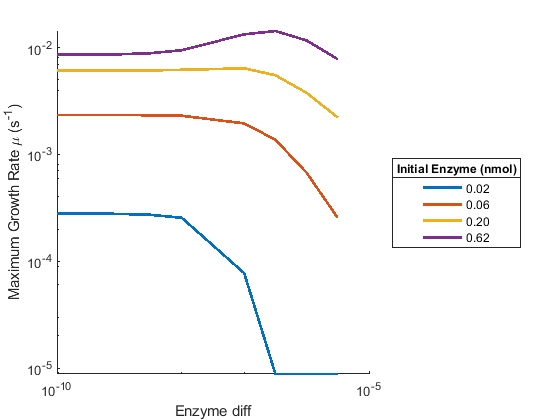

title(leg,'Initial Enzyme (nmol)');
set(gca,'yscale','log');
set(gca,'xscale','log');
hold off;

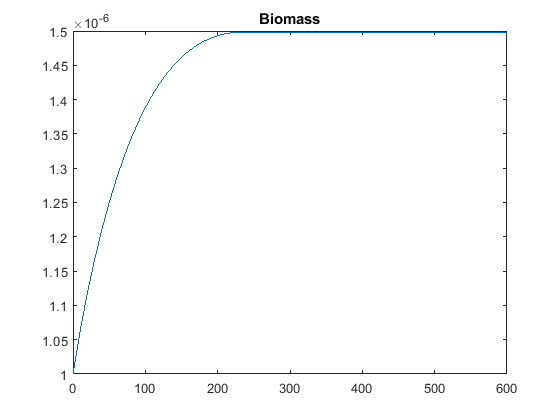

%draw some pretty circles
ei = sort(unique(dat10.enz_init));
d = dat10(dat10.enz_init == ei(3),:);
row = d(d.biomass_max == max(d.biomass_max),:);

plot(row.t{1},row.biomass_total{1});
xlim([0 600]);
title('Biomass');

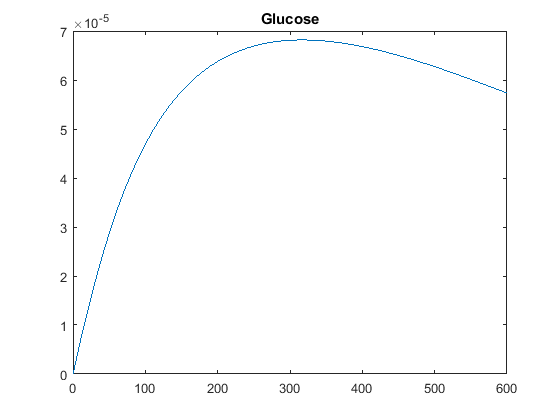

plot(row.t{1}(1:106),row.glc_total{1});
xlim([0 600]);
title('Glucose');

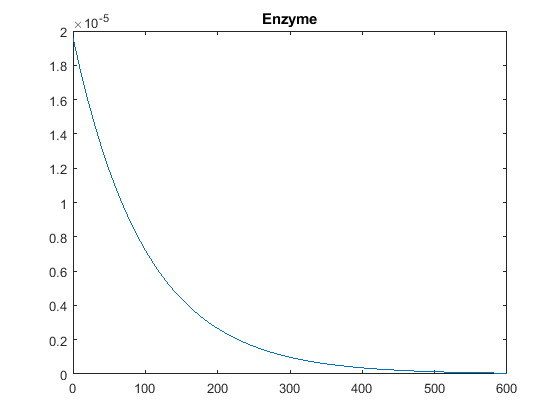

plot(row.t{1}(1:106),row.enz_total{1});
xlim([0 600]);
title('Enzyme');

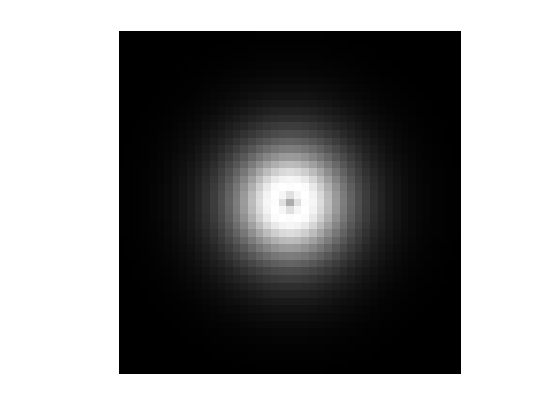


ts = 10;
glcmax = max(row.glc_coord{1}(:,:,ts));
glcmax = max(glcmax(:));
enzmax = max(row.enz_coord{1}(:,:,ts));
enzmax = max(enzmax(:));
gdata = row.glc_coord{1}(22:66,22:66,ts);
gdata = gdata ./ glcmax;
imshow(gdata);

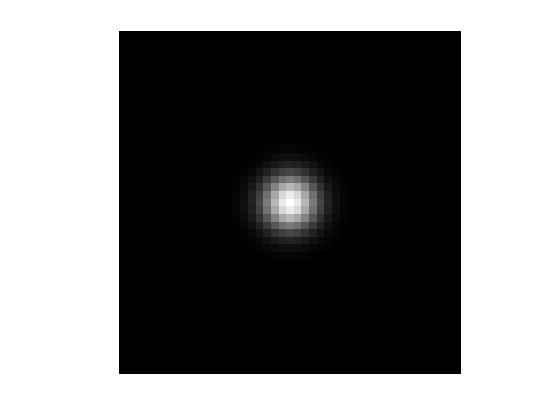

%heatmap(hmdata,'GridVisible','off','colorbarvisible','off');
edata = row.enz_coord{1}(22:66,22:66,ts);
edata = edata ./enzmax;
imshow(edata);

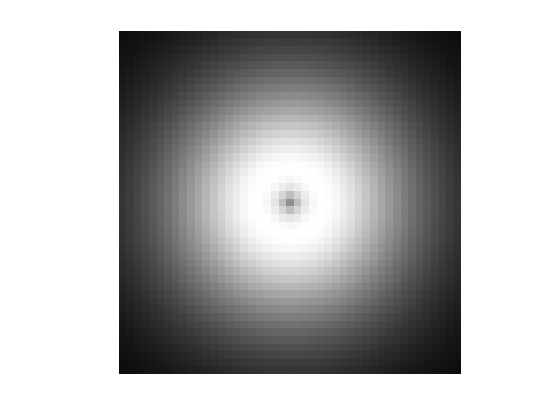


ts = 30;
glcmax = max(row.glc_coord{1}(:,:,ts));
glcmax = max(glcmax(:));
enzmax = max(row.enz_coord{1}(:,:,ts));
enzmax = max(enzmax(:));
gdata = row.glc_coord{1}(22:66,22:66,ts);
gdata = gdata ./ glcmax;
imshow(gdata);

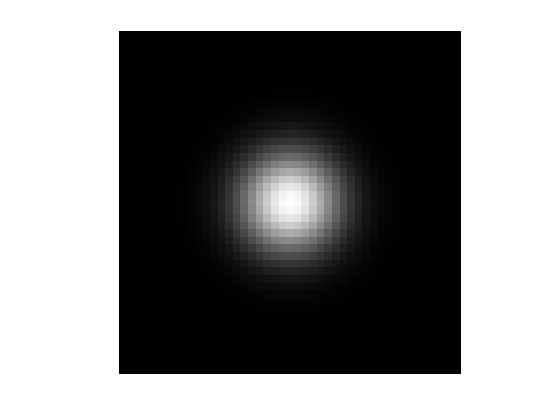

edata = row.enz_coord{1}(22:66,22:66,ts);
edata = edata ./enzmax;
imshow(edata);

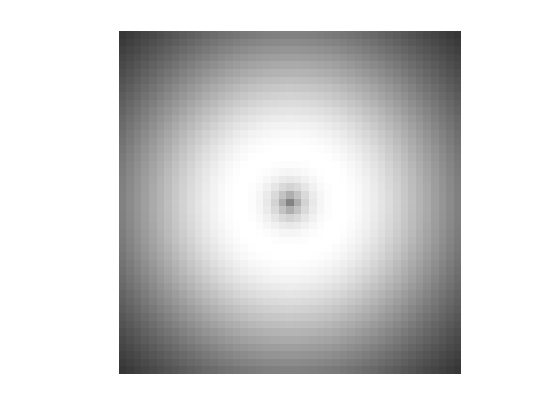


ts = 50;
glcmax = max(row.glc_coord{1}(:,:,ts));
glcmax = max(glcmax(:));
enzmax = max(row.enz_coord{1}(:,:,ts));
enzmax = max(enzmax(:));
gdata = row.glc_coord{1}(22:66,22:66,ts);
gdata = gdata ./ glcmax;
imshow(gdata);

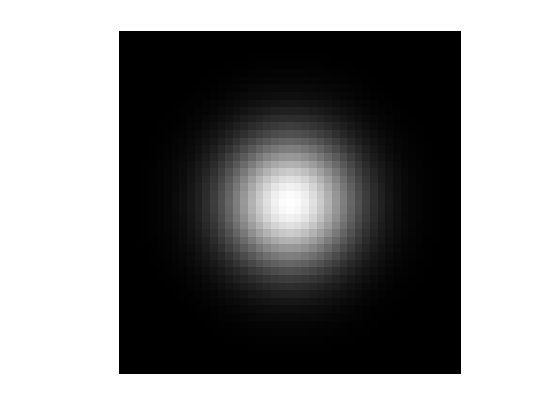

%heatmap(hmdata,'GridVisible','off','colorbarvisible','off');
edata = row.enz_coord{1}(22:66,22:66,ts);
edata = edata ./enzmax;
imshow(edata);